# Event-related analysis for even and jittered stimuli

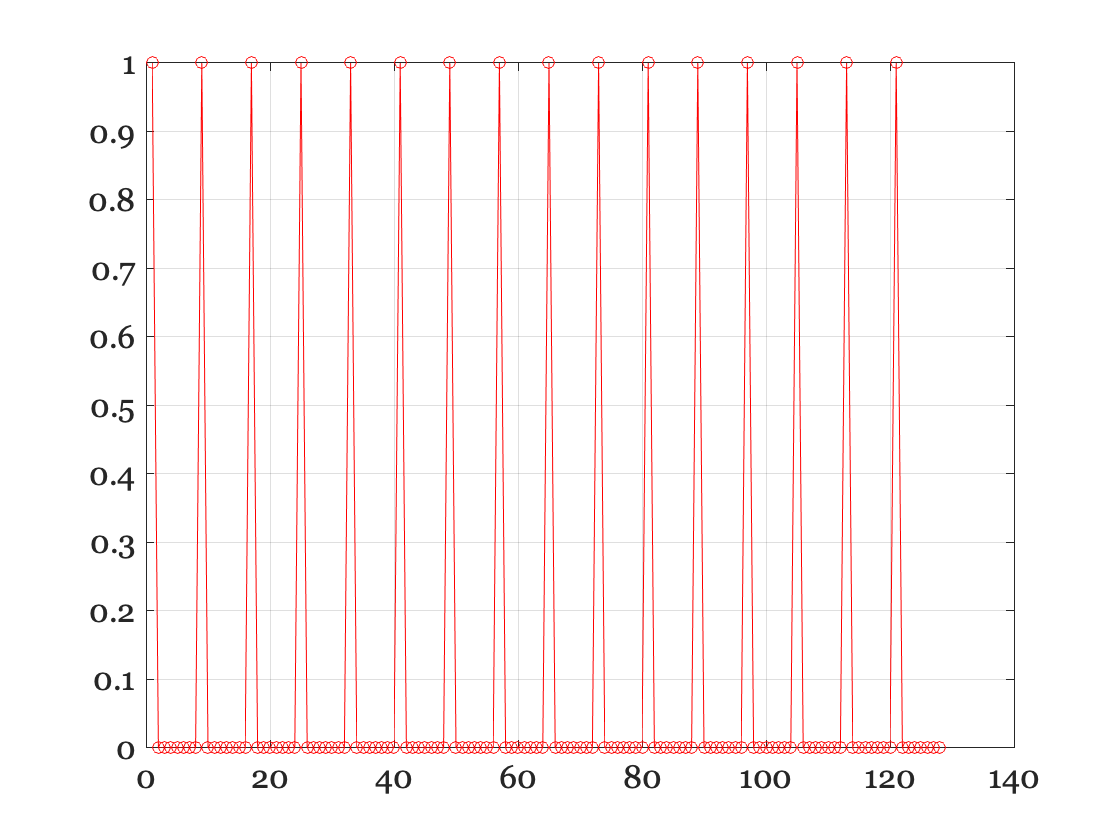

% 
% Background:
%   The student must understand that estimating the HRF is the same as
%   measuring the response at a set of different temporal frequencies.  We
%   get one estimate of the HRF from knowing the amplitude and phase of the
%   response to each temporal frequency.  If we do not use a particular
%   frequency in the input signal, then we will not be able to estimate
%   that frequency component of the HRF.
%
% Purpose:
%  Analyze what we might expect to measure about the kernel of a linear
%  system when we use evenly spaced events.
%
% Main Points:
%    1.  When the input events are evenly spaced, the input signal 
%    temporal energy is confined to a small number of frequency bands.  Hence,
%    the measured response is only an estimate of the properties of the HRF
%    at those (small number of) frequency bands.  We do not get information
%    about the HRF properties at other temporal frequencies -- because we
%    do not measure at those frequencies.
%
%    2.  When we randomly jitter the input signals, we get stimulus energy
%    at other input frequencies.  So, we can learn something about the HRF
%    properties at those frequencies.
%
%    3.  Finally, we must ask about the effect of the input signal energy
%    that is higher than the Nyquist sampling rate of the measured
%    response.  What happens to that energy?  This is still TODO.

% Even spacing of the inputs
%
% Suppose we have N sec in the input stimulus, and we keep time every second.
% Further, suppose we place events at delta intervals
N = 128; delta = 8;
% N = 128; delta = 32;

% The input series looks like
Stimulus = zeros(1,N);
e = 1:delta:128;
Stimulus(e) = 1;

figure; plot(Stimulus,'-o'); grid on;

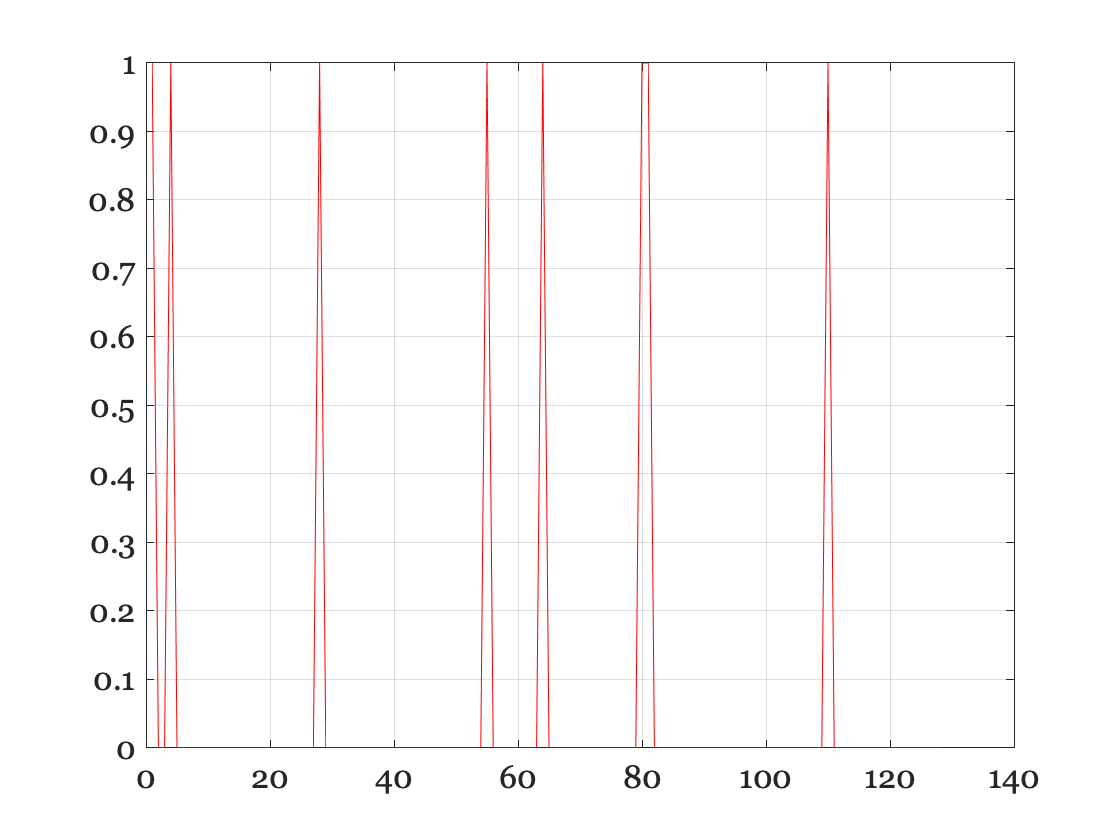


% Now, consider the Fourier Transform of this input series
%
StimulusFFT = abs(fft(Stimulus));
Frequency = [0:(N-1)]*(1/N);

% Now, consider the response.  Suppose it is sampled with a TR of 2 sec.
% Then, the maximum temporal response frequency (Hz) we can estimate is 
TR = 2;  maxFreq = 1 / (2*TR);

% The most we can hope to learn about is at frequencies defined by the TR,
responseFrequencies = [0:TR:(N-1)]*(1/N);

% Consider the stimulus frequencies below this level
figure(1)
fList = (Frequency < maxFreq);
plot(Frequency(fList),StimulusFFT(fList),'bo-');
hold on
fList = (responseFrequencies < maxFreq);
plot(responseFrequencies(fList),1,'ro')
hold off


xlabel('Frequency (Hz)');
ylabel('Amplitude');
grid on

% With this choice of (typical) parameters, we see that our effective input
% is restricted to energy at three stimulus frequencies (plus DC).  The
% estimate we obtain of the response function must be a weighted sum of the
% energy at these three temporal frequencies.

% Either think, or experiment, to understand what will happen when you
% change delta to a slower or faster sampling rate.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%Jitter the events
N = 128; delta = 16;
% N = 128; delta = 32;

% The input series looks like
Stimulus = zeros(1,128);
nEvents = round(N/delta);
e = round(rand(1,nEvents)*N);
Stimulus(e) = 1;

figure; plot(Stimulus); grid on;

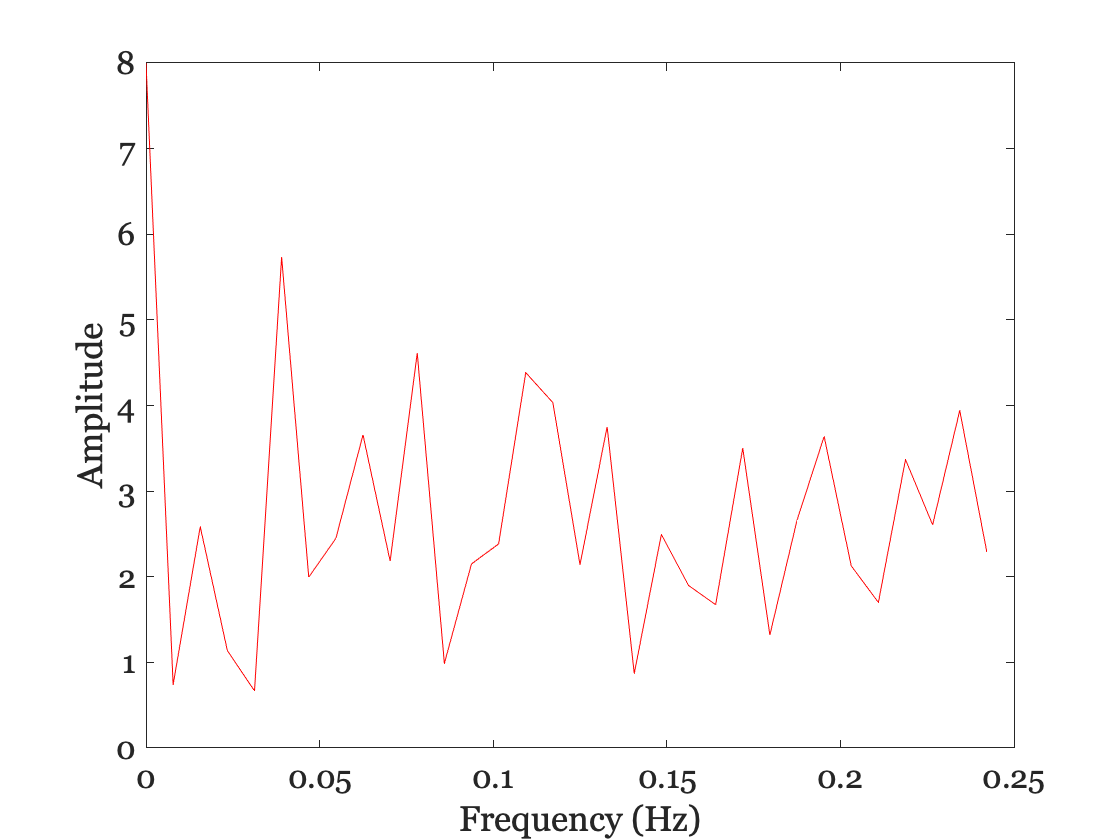


% Now, consider the Fourier Transform of this input series
%
StimulusFFT = abs(fft(Stimulus));
Frequency = 0:(1/128):(length(StimulusFFT)-1);

% Now, consider the response.  Suppose it is sampled with a TR of 2 sec.
% Then, the maximum temporal response frequency (Hz) we can estimate is 
TR = 2;  maxFreq = 1 / (2*TR);

% Consider the stimulus frequencies below this level
fList = (Frequency < maxFreq);
plot(Frequency(fList),StimulusFFT(fList))
xlabel('Frequency (Hz)');
ylabel('Amplitude');


% With this choice of (typical) parameters, we see that the effective input
% has energy at a broader range of temporal frequencies (plus DC).  The
% estimate we obtain of the response function must be a weighted sum of the
% these.  The amplitude at each of the frequencies, however,  is lower than
% the amplitude at the frequencies when we place the samples evenly in
% time.